% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\cubeWithHole.STL");

% Create UniformSliceGeneratorObject
sliceHeight = 1;
uSGO1 = FlatUniformSliceGenerator(stl1, sliceHeight)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [184×3 double]
       numOfElements: 184
              points: [92×3 int64]
      sliceThickness: 1
           slicePath: [0×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100



test = uSGO1.slice(10)

test =   100.0000   10.0000   10.0000
  100.0000  100.0000   10.0000
   95.3061  100.0000   10.0000
   94.8889  100.0000   10.0000
   94.1463  100.0000   10.0000
   92.9730  100.0000   10.0000
   91.5152  100.0000   10.0000
   89.6667  100.0000   10.0000
   87.8571  100.0000   10.0000
   85.3846  100.0000   10.0000


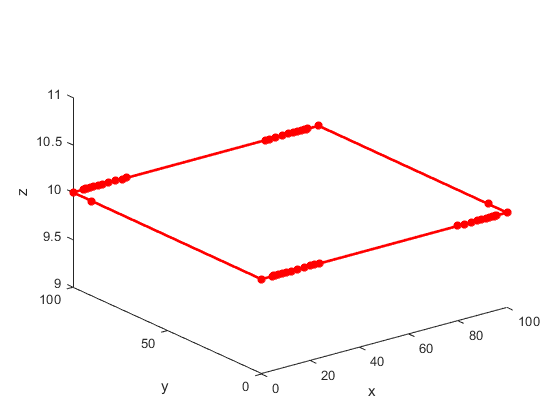

plot3(test(:,1), test(:,2), test(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
zlabel('z')


% Generate
figure(3)
uSGO1.generateSlices()

ans =    100     0     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0


ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [184×3 double]
       numOfElements: 184
              points: [92×3 int64]
      sliceThickness: 1
           slicePath: [4367×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100


op = uSGO1.getSlicePath()

op =    100     0     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0
   100   100     0


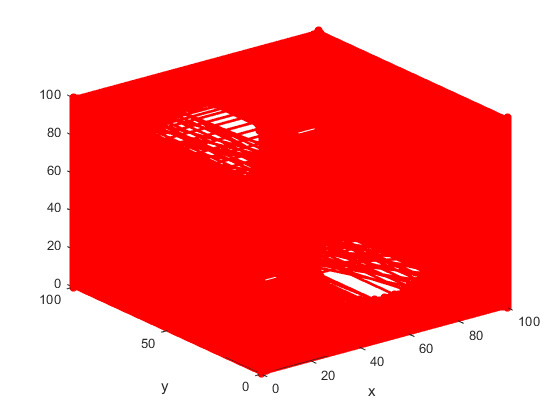


% Show
figure(4)

for i = 0:sliceHeight:max(op(:,3))
    
    plotPoints = op(op(:,3) == i,:);
    plot3(plotPoints(:,1), plotPoints(:,2), plotPoints(:,3),'-r*','LineWidth',2);
    hold on

end

xlabel('x')
ylabel('y')
view(3);
hold on